#  Load, register, segment and neuropil correct 2P data

## Path names

fn_base = '\\duhs-user-nc1.dhe.duke.edu\dusom_glickfeldlab\All_Staff';
lg_fn = fullfile(fn_base, 'home\lindsey');
data_fn = fullfile(lg_fn, 'Data\2P_images');
mworks_fn = fullfile(fn_base, 'Behavior\Data');
fnout = fullfile(lg_fn, 'Analysis\2P\test');

## Specific experiment information

date = '200825';
ImgFolder = '003';
time = '1248';
mouse = 'i1328';
frame_rate = 15.5;
run_str = catRunName(ImgFolder, 1);
datemouse = [date '_' mouse];
datemouserun = [date '_' mouse '_' run_str];

## Load 2P data

Load mworks data (stimulus and behavior information)

fName = fullfile(mworks_fn, ['data-' mouse '-' date '-' time '.mat']);
load(fName);

Load 2P metadata

CD = fullfile(data_fn, mouse, date, ImgFolder);
cd(CD);
imgMatFile = [ImgFolder '_000_000.mat'];
load(imgMatFile);

Load 2P images

totframes = input.counterValues{end}(end); %this is from the mworks structure- finds the last value clocked for frame count
fprintf(['Reading ' num2str(totframes) ' frames \r\n'])
data = sbxread([ImgFolder '_000_000'],0,totframes);

Data is nPMT x nYpix x nXpix x nframes. 

fprintf(['Data is ' num2str(size(data))])

When imaging a single channel, nPMT = 1, so squeeze:

data = squeeze(data);

## Register 2P data

Goal here is to remove X-Y movement artifacts

1. Find a stable target

    a. Plot average of 500 frames throughout stack

nframes = 500; %nframes to average
nskip = 1500; %nframes to skip for each average

nep = floor(size(data,3)./nskip);

Unrecognized function or variable 'data'.

[n n2] = subplotn(nep); 
figure('units','normalized','outerposition',[0 0 1 1]);
for i = 1:nep; 
    subplot(n,n2,i); 
    imagesc(mean(data(:,:,1+((i-1)*nskip):nframes+((i-1)*nskip)),3)); 
    title([num2str(1+((i-1)*nskip)) '-' num2str(nframes+((i-1)*nskip))]); 
end


    b. GUI to select target image- choose one that is sharp and close to center of stack

f=gcf;
w = waitforbuttonpress; %click on subplot
if w == 0
    axesClicked = gca;
    allAxes = flipud(findobj(f.Children,'Type','axes'));
    numClicked = find(axesClicked==allAxes);
    close all
end
fprintf(['Selected subplot ' num2str(numClicked)])

    c. Create target image

data_avg = mean(data(:,:,1+((numClicked-1)*nskip):nframes+((numClicked-1)*nskip)),3); 

2. stackRegister minimizes the difference of each frame from the target

[out, data_reg] = stackRegister(data,data_avg);

New average image after registration

data_reg_avg = mean(data_reg,3);

Save registration shifts and target, and mworks data

mkdir(fullfile(fnout, datemouse, datemouserun))
save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_reg_shifts.mat']), 'data_reg_avg', 'out', 'data_avg')
save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_input.mat']), 'input')

Test registration

    a. Make sure first and last images are sharp and similar. Focus on vasculature and nuclei- not cells since F changes

ind = [1 nep];
for i = 1:length(ind) 
    subplot(2,1,i); 
    ix = ind(i);
    imagesc(mean(data_reg(:,:,1+((ix-1)*nskip):nframes+((ix-1)*nskip)),3)); 
    title([num2str(1+((ix-1)*nskip)) '-' num2str(nframes+((ix-1)*nskip))]); 
end
print(fullfile(fnout, datemouse, datemouserun, [datemouserun '_FOV_first&last.pdf']), '-dpdf')

    b. Average of all frames should be sharp

imagesq(data_reg_avg); 
print(fullfile(fnout, datemouse, datemouserun, [datemouserun '_FOV_avg.pdf']), '-dpdf')
clear data

## Segment 2P data

Goal here is to create a cell mask to extract fluorescence timecourses

1. Find activated cells

    a. Reshape data stack to segregate trials 

    First need to know how many frames per trial and how many trials

nOn = input.nScansOn;
nOff = input.nScansOff;
ntrials = size(input.tGratingDirectionDeg,2); %this is a cell array with one value per trial, so length = ntrials
sz = size(data_reg);

        Each trial has nOff frames followed by nOn frames, so can reshape stack so nYpix x nXpix x nFrames/Trial (nOn+nOff) x nTrials

data_tr = reshape(data_reg,[sz(1), sz(2), nOn+nOff, ntrials]);
fprintf(['Size of data_tr is ' num2str(size(data_tr))])

Size of data_tr is 264  796  180  160

    b. Find baseline F from last half of off period- avoids decay of previous on trial

data_f = mean(data_tr(:,:,nOff/2:nOff,:),3); 

    c. Find dF/F for each trial

data_df = bsxfun(@minus, double(data_tr), data_f); 
data_dfof = bsxfun(@rdivide,data_df, data_f); 
clear data_f data_df data_tr

    d. Find average dF/F for each stimulus condition (this is for an experiment with changing grating direction)

Dir = celleqel2mat_padded(input.tGratingDirectionDeg); %transforms cell array into matrix (1 x ntrials)
Dirs = unique(Dir);
nDirs = length(Dirs);
data_dfof_avg = zeros(sz(1),sz(2),nDirs); %create empty matrix with FOV for each direction: nYpix x nXPix x nDir

nStim = nDirs;
[n n2] = subplotn(nDirs); %function to optimize subplot number/dimensions
for idir = 1:nDirs
    ind = find(Dir == Dirs(idir)); %find all trials with each direction
    data_dfof_avg(:,:,idir) = mean(mean(data_dfof(:,:,nOff+1:nOn+nOff,ind),3),4); %average all On frames and all trials
    subplot(n,n2,idir)
    imagesc(data_dfof_avg(:,:,idir))
end
clear data_dfof

        Filtering data helps make cells more visible for selection

myfilter = fspecial('gaussian',[20 20], 0.5);
data_dfof_avg_all = imfilter(data_dfof_avg,myfilter);
data_dfof_max = max(data_dfof_avg_all,[],3); %finds all active cells by taking max projection

save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_stimActFOV.mat']), 'data_dfof_max', 'data_dfof_avg_all', 'nStim')

    2. Create cell masks from active cells

        Concatenate images of max and all directions

data_dfof = cat(3,data_dfof_max, data_dfof_avg_all);

        Set up empty matrices for segmenting cells

mask_data = data_dfof;
mask_exp = zeros(sz(1),sz(2));
mask_all = zeros(sz(1), sz(2));

        a. Click on bright cells in mask to create mask- blue shading should fill bright region of single cell evenly.  

            If cell not filled well, press 'z' or shift+click to remove. Try again by 1) clicking on different spot- brighter spot will make fill smaller- if there are two cells also helps to fill brighter cell first; 2) change threshold- higher thresh will make fill smaller; 3) wait for different image where cell might be more distinct from background

            Press 'return' when done with each image. 

            Next images will have black spots where cells were previously selected- don't let new masks encroach on old cells or will fuse. imCellBuffer helps with this.

Added object #1: 27 pix


Deleted object, 0 total remain


Added object #1: 89 pix


Added object #2: 64 pix


Added object #3: 78 pix


Deleted object, 2 total remain


Added object #3: 75 pix


Added object #4: 41 pix


Deleted object, 3 total remain


Added object #4: 64 pix


Added object #5: 66 pix


Added object #6: 96 pix


Added object #7: 60 pix


Added object #8: 75 pix


Added object #9: 99 pix


Deleted object, 8 total remain


Added object #9: 96 pix


Added object #10: 68 pix


Added object #11: 52 pix


Deleted object, 10 total remain


Added object #11: 18 pix


Deleted object, 10 total remain


Added object #11: 58 pix


** Trying to delete, not on a cell, try again


Added object #12: 62 pix


Deleted object, 11 total remain


Added object #12: 40 pix


Deleted object, 11 total remain


Added object #12: 88 pix


Deleted object, 11 total remain


Unrecognized click occurred (matlab bug?) alt, 261 145


Added object #12: 46 pix


Deleted object, 11 total remain


Added object #12: 45 pix


Added object #13: 30 pix


Added object #14: 93 pix


Added object #15: 68 pix


Deleted object, 14 total remain


Added object #15: 96 pix


** Trying to add in existing cell region, try again


** Trying to add in existing cell region, try again


Added object #16: 66 pix


Added object #17: 64 pix


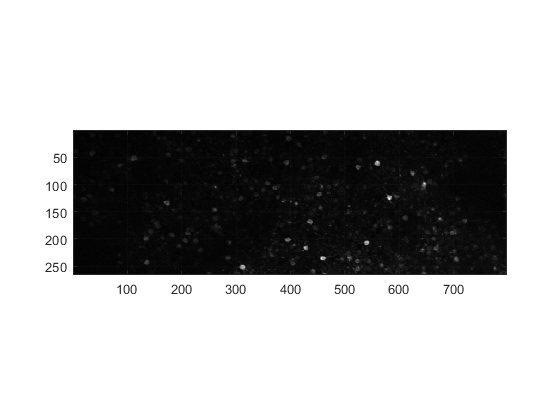

imCellEditInteractiveLG: done, 17 objects total).


Added object #1: 43 pix


Deleted object, 0 total remain


Added object #1: 85 pix


Added object #2: 101 pix


Added object #3: 29 pix


Added object #4: 69 pix


Added object #5: 95 pix


Added object #6: 56 pix


Added object #7: 76 pix


Added object #8: 73 pix


Added object #9: 34 pix


Deleted object, 8 total remain


Added object #9: 108 pix


Added object #10: 74 pix


Added object #11: 125 pix


** Trying to add in existing cell region, try again


Added object #12: 82 pix


Added object #13: 89 pix


Added object #14: 59 pix


imCellEditInteractiveLG: done, 14 objects total).


Added object #1: 53 pix


Added object #2: 53 pix


Added object #3: 45 pix


Deleted object, 2 total remain


Added object #3: 85 pix


Added object #4: 104 pix


Added object #5: 63 pix


Added object #6: 83 pix


Added object #7: 65 pix


Added object #8: 42 pix


Deleted object, 7 total remain


Added object #8: 63 pix


Added object #9: 51 pix


Added object #10: 59 pix


Added object #11: 106 pix


Added object #12: 57 pix


Added object #13: 91 pix


Added object #14: 68 pix


imCellEditInteractiveLG: done, 14 objects total).


Added object #1: 70 pix


Added object #2: 52 pix


Added object #3: 58 pix


Added object #4: 99 pix


Added object #5: 73 pix


Added object #6: 64 pix


Added object #7: 67 pix


Added object #8: 111 pix


Added object #9: 72 pix


Added object #10: 62 pix


Added object #11: 65 pix


Added object #12: 79 pix


Added object #13: 95 pix


Added object #14: 26 pix


Deleted object, 13 total remain


Added object #14: 137 pix


Added object #15: 65 pix


Added object #16: 24 pix


** Trying to delete, not on a cell, try again


Deleted object, 15 total remain


Added object #16: 117 pix


imCellEditInteractiveLG: done, 16 objects total).


Added object #1: 55 pix


Added object #2: 59 pix


Added object #3: 50 pix


Added object #4: 45 pix


Added object #5: 70 pix


Added object #6: 62 pix


imCellEditInteractiveLG: done, 6 objects total).


Added object #1: 36 pix


Deleted object, 0 total remain


Added object #1: 45 pix


Added object #2: 100 pix


Added object #3: 92 pix


Added object #4: 34 pix


Added object #5: 43 pix


Added object #6: 68 pix


Added object #7: 21 pix


Added object #8: 66 pix


Added object #9: 53 pix


Added object #10: 82 pix


Added object #11: 36 pix


imCellEditInteractiveLG: done, 11 objects total).


Added object #1: 60 pix


Added object #2: 34 pix


Added object #3: 48 pix


Added object #4: 18 pix


imCellEditInteractiveLG: done, 4 objects total).


Added object #1: 79 pix


Added object #2: 85 pix


Added object #3: 67 pix


Added object #4: 42 pix


Added object #5: 63 pix


Added object #6: 86 pix


Added object #7: 80 pix


imCellEditInteractiveLG: done, 7 objects total).


Added object #1: 73 pix


Added object #2: 60 pix


Added object #3: 52 pix


Added object #4: 31 pix


Deleted object, 3 total remain


Added object #4: 40 pix


Deleted object, 3 total remain


Added object #4: 104 pix


Added object #5: 91 pix


Added object #6: 45 pix


Added object #7: 90 pix


Added object #8: 99 pix


Added object #9: 57 pix


imCellEditInteractiveLG: done, 9 objects total).


Added object #1: 63 pix


Added object #2: 69 pix


Added object #3: 63 pix


Added object #4: 49 pix


imCellEditInteractiveLG: done, 4 objects total).


Added object #1: 70 pix


Added object #2: 40 pix


Added object #3: 67 pix


imCellEditInteractiveLG: done, 3 objects total).


Added object #1: 79 pix


Added object #2: 41 pix


Added object #3: 56 pix


Added object #4: 44 pix


Added object #5: 54 pix


Added object #6: 55 pix


Added object #7: 109 pix


Added object #8: 36 pix


Deleted object, 7 total remain


Added object #8: 109 pix


Added object #9: 106 pix


Added object #10: 55 pix


imCellEditInteractiveLG: done, 10 objects total).


Added object #1: 77 pix


Added object #2: 94 pix


Added object #3: 99 pix


Added object #4: 76 pix


Added object #5: 66 pix


Added object #6: 67 pix


Added object #7: 60 pix


imCellEditInteractiveLG: done, 7 objects total).


Added object #1: 86 pix


Added object #2: 60 pix


Added object #3: 35 pix


Added object #4: 64 pix


Deleted object, 3 total remain


Added object #4: 66 pix


Added object #5: 97 pix


Added object #6: 69 pix


Added object #7: 70 pix


imCellEditInteractiveLG: done, 7 objects total).


Added object #1: 89 pix


Added object #2: 101 pix


Added object #3: 55 pix


imCellEditInteractiveLG: done, 3 objects total).


Added object #1: 99 pix


imCellEditInteractiveLG: done, 1 objects total).


Added object #1: 27 pix


Added object #2: 59 pix


Deleted object, 1 total remain


Added object #2: 56 pix


Added object #3: 111 pix


Added object #4: 23 pix


Added object #5: 90 pix


imCellEditInteractiveLG: done, 5 objects total).


for iStim = 1:size(data_dfof,3)    
    mask_data_temp = mask_data(:,:,iStim);
    mask_data_temp(find(mask_exp >= 1)) = 0; %blacks out old cells
    bwout = imCellEditInteractiveLG(mask_data_temp); %selection GUI
    mask_all = mask_all+bwout; %adds new cells to old cells
    mask_exp = imCellBuffer(mask_all,3)+mask_all; %creates buffer around cells to avoid fusing
    close all
end

        b. Number independent regions for mask

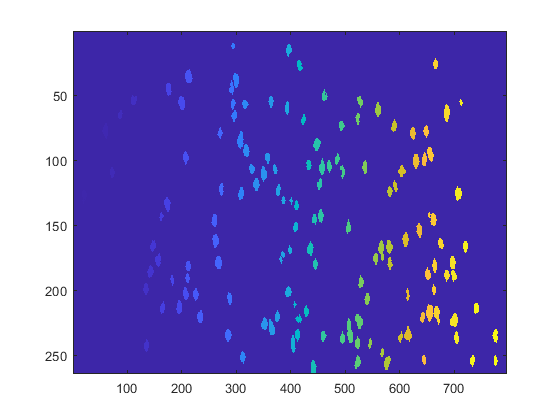

mask_cell = bwlabel(mask_all); %turns logical into numbered cells
figure;
imagesc(mask_cell)

        c. Create neuropil masks (these are regions around each cell without overlap from neighboring cells)

nMaskPix = 5; %thickness of neuropil ring in pixels
nBuffPix = 3; %thickness of buffer between cell and ring
mask_np = imCellNeuropil(mask_cell,nBuffPix,nMaskPix);

save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_mask_cell.mat']), 'data_dfof_max', 'mask_cell', 'mask_np')
clear data_dfof data_dfof_avg max_dfof mask_data mask_all mask_2 data_base data_base_dfof data_targ data_targ_dfof data_f data_base2 data_base2_dfof data_dfof_dir_all data_dfof_max data_dfof_targ data_avg data_dfof2_dir data_dfof_dir 

## Neuropil subtraction

Goal is to remove contamination from out-of-focus fluorescence

- Extract cell timecourses

data_tc = stackGetTimeCourses(data_reg, mask_cell); %applies mask to stack to get timecourses

Unrecognized function or variable 'data_reg'.

            Timecourses are nFrames x nCells

fprintf(['data_tc is ' num2str(size(data_tc))]) 
nCells = size(data_tc,2);

            Downsampled timecourses for neuropil subtraction- averageing decreases noise

down = 5; %number of frames to average
data_reg_down = stackGroupProject(data_reg,down); %averages every 5 frames in stack  
data_tc_down = stackGetTimeCourses(data_reg_down, mask_cell);    

        2.  Extract neuropil timecourses (full and downsampled)

sz = size(data_reg);
np_tc = zeros(sz(3),nCells);
np_tc_down = zeros(floor(sz(3)./down), nCells);
for i = 1:nCells
     np_tc(:,i) = stackGetTimeCourses(data_reg,mask_np(:,:,i));
     np_tc_down(:,i) = stackGetTimeCourses(data_reg_down,mask_np(:,:,i));
     fprintf(['Cell #' num2str(i) '%s\n']) 
end

        3. Find best neuropil weights by maximizing skew on downsampled subtractions

            Assumes calcium signals are 1) sparse and 2) positive.  Too little subtraction will decrease sparseness and too much will make signals negative. Thus, the best neuropil subtraction should yield the highest skew.

        a. Measure skew for all weights:

ii= 0.01:0.01:1;
x = zeros(length(ii), nCells);
for i = 1:100
    x(i,:) = skewness(data_tc_down-tcRemoveDC(np_tc_down*ii(i)));
end

        b. Find index with highest skew for each cell

[max_skew ind] =  max(x,[],1); 

        c. convert to weight

np_w = 0.01*ind; 

        4. Subtract weighted neuropil response from full timecourses

npSub_tc = data_tc-bsxfun(@times,tcRemoveDC(np_tc),np_w);
clear data_reg data_reg_down

save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_TCs.mat']), 'data_tc', 'np_tc', 'npSub_tc')